# **IIT Bomaby, Student Satellite Program**

# **Star Tracker-based Attitude Determination System (STADS)**

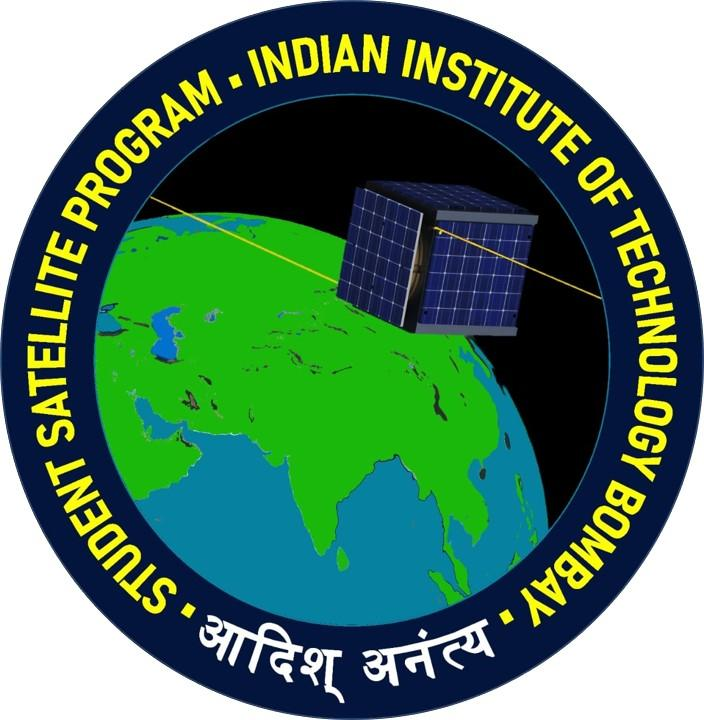

# **Model-in-Loop Simulation Framework**

## **Version - 1.0**

 
clear
clc

# **Simuation Details**

% Manual Entry
sim_log.operator = "K T Prajwal Prathiksh"; % Enter Simulation Operator's Full Name
sim_log.operator_ID = "KTPP"; % Enter Operator ID
sim_log.sim_ID = "10"; % Enter Simulation Number
sim_log.path = "E:\IIT Bombay\SatLab\Star Tracker\Star Matching\STADS\MILS\Simulation_1"; % Enter Path of Simulation Folder

% Automated Entry
sim_log.date = datestr(now, 'dd/mm/yyyy');
sim_log.time = datestr(now, 'HH:MM:SS.FFF');
sim_log.computerName = getenv('computername');
sim_log.userName= getenv('username');
sim_log.output_path = sim_log.path + '\Output';

 

# Star Image Simulation

### Model

- Setting **Version == NONE, will not run **Star Image Simulation

if ~exist('sim_log')
    error("SimulationError: Simulation Details Not Loaded!")
end
sim_log.SIS.version = "Version - 3";
 

### **Load Inputs & Constants**

if sim_log.SIS.version ~= "NONE"
   
    % Add Simulation Path
    addpath(genpath(sim_log.path));
    
    %% Load Inputs & Constants File
    if isfile(sim_log.path + "\inputs.csv") == 0
        error('FileNotFoundError: input.csv file - missing!');
    elseif isfile(sim_log.path + "\constants.m") == 0
        error('FileNotFoundError: constants.m file -  missing!');
    elseif isfile(sim_log.path + "\constants.mat") == 0
        error('FileNotFoundError: constants.mat file - missing!');
    else
        load(sim_log.path + "\constants.mat");
        INPUT = readtable(sim_log.path + "\inputs.csv");   
        sim_log.N_Iter = INPUT.Sl_No(end);
    end
    disp("Done: Load Inputs & Constants");

### Generate Star Image Simulation - Log File

    tic
    % Read SIS-data file
    if sim_log.SIS.version == "Default Block"
        %%%%%% Load Default Block data
    elseif sim_log.SIS.version == "Version - 3"
        %%%%%% Load Version - 3 data
    end
    
    %% Make Output Folder
    mkdir(sim_log.output_path);
    
    %% Create SIS_log.txt file
    SIS_logFile = fopen(sim_log.path + "\SIS_log.md",'w');
    fprintf(SIS_logFile,'# Star Image Simulation - Log File\n\n');
    fprintf(SIS_logFile,'## Simulation ID: %s\n\n', sim_log.sim_ID);
    % Simulation Details
    fprintf(SIS_logFile,'## Simulation - Details\n');
    fprintf(SIS_logFile,'* **Operator**: %s\n', sim_log.operator);
    fprintf(SIS_logFile,'* **Operator ID**: %s\n', sim_log.operator_ID);
    fprintf(SIS_logFile, '* **Date**: %s\n', sim_log.date);
    fprintf(SIS_logFile, '* **Time**: %s\n', sim_log.time);
    fprintf(SIS_logFile, '* **Computer**: %s\n', sim_log.computerName);
    fprintf(SIS_logFile, '* **User**: %s\n\n', sim_log.userName);
    % Star Image Simulation Details
    fprintf(SIS_logFile,'## Star Image Simulation - Details\n');
    fprintf(SIS_logFile,'* **Version**: %s\n\n', sim_log.SIS.version);
    %%%%%% Print additional SIS details
    fprintf(SIS_logFile,'## Simulation - Details\n\n');
    fprintf(SIS_logFile,'Iter|Status|Time_Taken **(HH:MM:SS)**\n');
    
    disp("Done: Generate SIS_log.m & \Output Folder");

### **Run Star Image Simulation**

    sim_log.T1 = datetime();
    disp('Start: Star Image Simulation');
    ProgBar = waitbar(0,'Starting simulation...');
    for i = 1:sim_log.N_Iter
        iter_info.i = i;
        waitbar(i/sim_log.N_Iter, ProgBar, 'Running simulation...');
        iter_info.t1 = datetime();
        
        %% Read Input
        sis_input.attitude = [INPUT.Attitude_1, INPUT.Attitude_2, INPUT.Attitude_3];
        
        %% Run Star Image Simulation on single input
        
        %%%%% sis_output = sis_main(sis_input, SIS_const, sim_log.sis_data.version)   
        sis_output.test1 = 10;
        sis_output.test2 = -10;
        
        
        %% Write log file & SIS-output
        iter_info.status = "Done";
        iter_info.fileName = sim_log.output_path + "\SIS_iter_" + string(iter_info.i) + ".mat";
        iter_info.dt = datetime() - iter_info.t1;  
        
        save(iter_info.fileName, 'sis_input', 'sis_output', 'iter_info'); % Save .mat file   
        fprintf(SIS_logFile,'%d|%s|%s\n', round(iter_info.i), iter_info.status, iter_info.dt); % Write log file entry
    end
    close(ProgBar);
    disp('Done: Star Image Simulation');
    sim_log.dt = datetime() - sim_log.T1;
    fprintf(SIS_logFile,'\nTotal Time Taken: %s\n', sim_log.dt);
    fclose(SIS_logFile);
    
    % Save SIS_log.mat
    SIS_log = sim_log;
    save(sim_log.output_path + "\SIS_log.mat", 'SIS_log');
    
    % Clear redundant variables
    clear
    toc
end

Done: Load Inputs & Constants


Done: Generate SIS_log.m & \Output Folder


Start: Star Image Simulation


Done: Star Image Simulation


Elapsed time is 1.188770 seconds.


# Model-In-Loop Simulation

### Model

if ~exist('sim_log')
    error("SimulationError: Simulation Details Not Loaded!")
end
sim_log.MILS.fe_data.algo = "Region Growth";
sim_log.MILS.sm_data.algo = "4-Star Matching";
sim_log.MILS.es_data.algo = "ESOQ2";
 

### Load Inputs & Constants

% Add Simulation Path
addpath(genpath(sim_log.path));

%% Load Inputs & Constants File
if isfolder(sim_log.output_path) == 0
    error('FolderNotFoundError: .\Output folder - missing!');
elseif isfile(sim_log.output_path + "\SIS_log.mat") == 0
    error('FileNotFoundError: SIS_log.mat - missing!');
elseif isfile(sim_log.path + "\SIS_log.md") == 0
    error('FileNotFoundError: SIS.md file - missing!');
elseif isfile(sim_log.path + "\constants.mat") == 0
    error('FileNotFoundError: constants.mat file - missing!');
elseif isfile(sim_log.path + "\inputs.csv") == 0
    error('FileNotFoundError: input.csv file - missing!');
else
    load(sim_log.path + "\constants.mat");
    load(sim_log.output_path + "\SIS_log.mat");
    sim_log.N_Iter = SIS_log.N_Iter;
end
disp("Done: Load Inputs & Constants");

Done: Load Inputs & Constants


### Generate Model-in-Loop Simulation - log file

%%% Read MILS-data files

%% Feature Extraction Data
if sim_log.MILS.fe_data.algo == "Default Block"
    %%%%%% Load Default Block data
elseif sim_log.MILS.fe_data.algo == "Region Growth"
    %%%%%% Load RG Block data
elseif sim_log.MILS.fe_data.algo == "Line-by-Line"
    %%%%%% Load LBL Block data
end

%% Create MILS_log.md file
MILS_logFile = fopen(sim_log.path + "\MILS_log.md",'w');
fprintf(MILS_logFile,'# Model-in-Loop Simulation - Log File\n');
fprintf(MILS_logFile,'\n## Simulation ID: %s\n', sim_log.sim_ID);
% Simulation Details
fprintf(MILS_logFile,'\n## Simulation - Details\n');
fprintf(MILS_logFile,'* **Operator**: %s\n', sim_log.operator);
fprintf(MILS_logFile,'* **Operator ID**: %s\n', sim_log.operator_ID);
fprintf(MILS_logFile, '* **Date**: %s\n', sim_log.date);
fprintf(MILS_logFile, '* **Time**: %s\n', sim_log.time);
fprintf(MILS_logFile, '* **Computer**: %s\n', sim_log.computerName);
fprintf(MILS_logFile, '* **User**: %s\n', sim_log.userName);
% Model-in-Loop Simulation Details
fprintf(MILS_logFile,'\n## Model-in-Loop Simulation - Details\n');
fprintf(MILS_logFile,'* **Feature Extraction - Algorithm**: %s\n', sim_log.MILS.fe_data.algo);
fprintf(MILS_logFile,'* **Star-Matching - Algorithm**: %s\n', sim_log.MILS.sm_data.algo);
fprintf(MILS_logFile,'* **Estimation - Algorithm**: %s\n', sim_log.MILS.es_data.algo);
%%%%%% Print additional MILS details
fprintf(MILS_logFile,'\n## Simulation - Details\n');
fprintf(MILS_logFile,'\nIter|FE-Status|SM-Status|ES-Status|Time_Taken **(HH:MM:SS)**\n');
fclose(MILS_logFile);

disp("Done: Generate MILS_log.md");

Done: Generate MILS_log.md
